clc; clear;

stik = 40;     % Antal stikprøver
tests = 100;     % Antal terningekast / udtagelser af stikprøven
test_range = [30, 35];
step = 0.25;

ms = zeros(1, stik);
Y = zeros(stik, tests);

for i = 1:stik
    for j = 1:tests
        Y(i,j) = randi(test_range, 1);
    end
    ms(i) = mean(Y(i,:));
end


histogram(ms, min(test_range):step:max(test_range), "Normalization","pdf")
hold on

% Den gennemsnitlige afvigelse
mean_gns = mean(ms)

mean_gns = 32.4797

stdafv = std(ms, 1)

stdafv = 0.1553

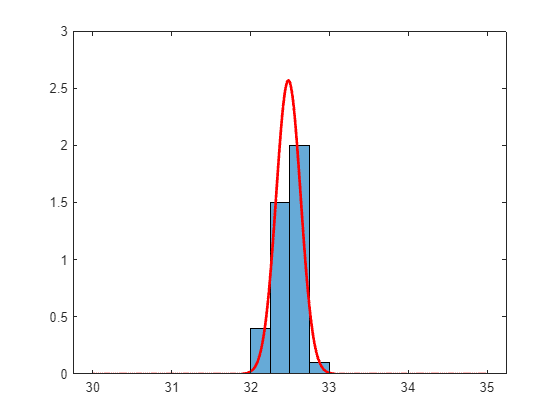


% PLotte fordelingen oveni
dist = makedist("Normal","mu",mean_gns,"sigma",stdafv);
x = linspace(min(test_range), max(test_range), 1000);

df = pdf(dist, x);

plot(x, df, Color="red", LineStyle="-", LineWidth=2)
hold off





dist2 = makedist("Normal", "mu",mean_gns,"sigma",stdafv)

dist2 =   NormalDistribution

  Normal distribution
       mu =  32.4797
    sigma = 0.155346



df2 = random(dist2, stik*tests, 1);


[h,p,stats] = chi2gof(df2,'Alpha', 0.05)

h = 0

p = 0.6546

stats = struct with fields:
    chi2stat: 5.0439
          df: 7
       edges: [31.9225 32.0325 32.1425 32.2524 32.3624 32.4724 32.5823 32.6923 32.8023 32.9122 33.0222]
           O: [10 48 257 617 990 1057 658 271 78 14]
           E: [9.8865 58.1664 238.0666 615.0848 1.0040e+03 1.0357e+03 675.3363 278.2141 72.3607 13.1793]


clc; clear;

step = 7;

data = importdata("Log Data 18-04-2023 09.22.38.txt");

ohms = data.data(:, 2);


mean_gns = mean(ohms)

mean_gns = 3.2140e+04

stdafv = std(ohms, 1)

stdafv = 35.0025




dist2 = makedist("Normal", "mu",mean_gns,"sigma",stdafv)

dist2 =   NormalDistribution

  Normal distribution
       mu = 32139.6
    sigma = 35.0025



df2 = random(dist2, 100, 1);

[h,p,stats] = chi2gof(df2,'Alpha', 0.05)

h = 0

p = 0.0848

stats = struct with fields:
    chi2stat: 8.1932
          df: 4
       edges: [3.2022e+04 3.2079e+04 3.2098e+04 3.2117e+04 3.2136e+04 3.2155e+04 3.2174e+04 3.2213e+04]
           O: [10 10 14 13 28 14 11]
           E: [7.8896 10.6957 16.8338 20.3541 18.9075 13.4933 11.8261]


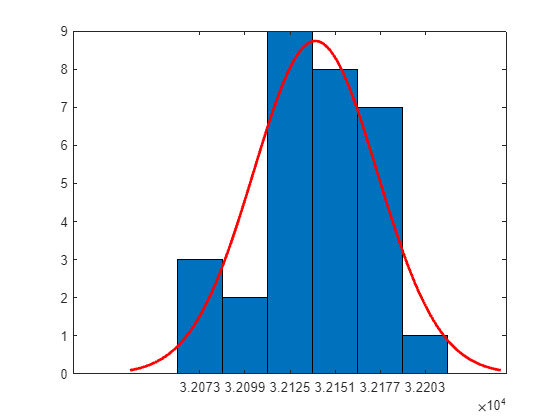


histfit(ohms)

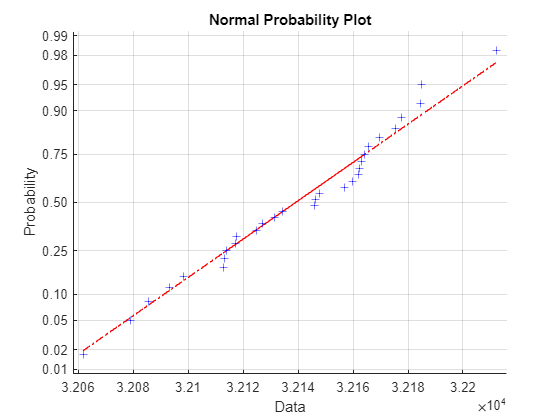



normplot(ohms)

clc; clear;

d1 = importdata("Log-Data-17-04-2023-12.54.19.txt");
d2 = importdata("Log-Data-17-04-2023-15.20.19.txt");


d1_ohm = d1.data(:, 2)';
d1_volt = d2.data(:, 2)';



deskripts([d1_ohm;d1_volt],["Data 1", "Data 2"])

    Datanavn    Middelværdi    Varians    Standardafvigelse    Målepunkter
    ________    ___________    _______    _________________    ___________

    "Data 1"       17220       279.98          16.733              30     
    "Data 2"       17194       206.96          14.386              30     



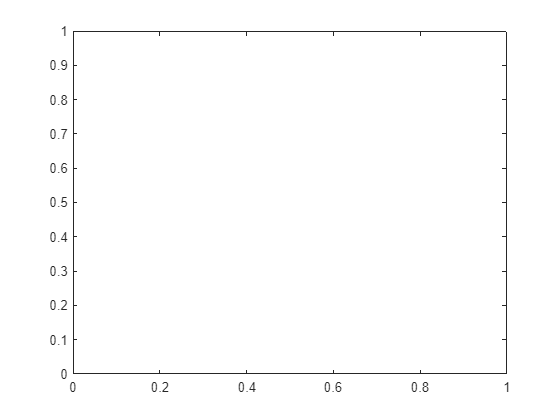


n = 30;

plothandle = plot(NaN, NaN);

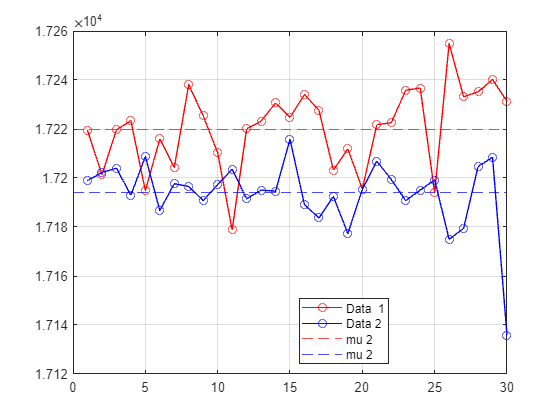




plot(1:30, d1_ohm, '-o', Color='r',DisplayName="Data  1"), grid("on")
hold on

plot(1:30, d1_volt, '-o',Color='b',DisplayName="Data 2")

yline(17220,'--', Color='r',DisplayName="mu 2")
yline(17194,'--', Color='b',DisplayName="mu 2")

legend('show', 'location','best')

hold off


clc; clear;

d1 = importdata("Log-Data-17-04-2023-12.54.19.txt");
d2 = importdata("Log-Data-17-04-2023-15.20.19.txt");


d1_ohm = d1.data(:, 2)';
d1_volt = d2.data(:, 2)';



deskripts([d1_ohm;d1_volt],["Data 1", "Data 2"])

    Datanavn    Middelværdi    Varians    Standardafvigelse    Målepunkter
    ________    ___________    _______    _________________    ___________

    "Data 1"       17220       279.98          16.733              30     
    "Data 2"       17194       206.96          14.386              30     



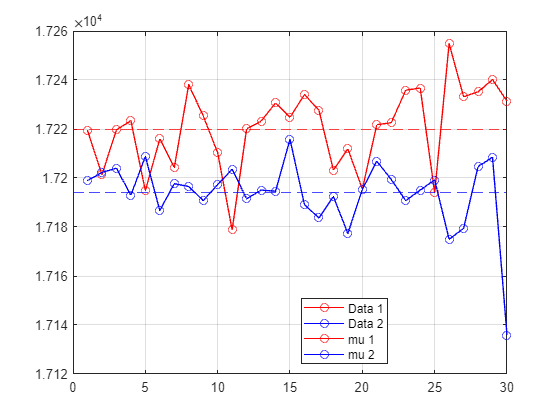


n = 30;

for i = 1:n

plot(1:i, d1_ohm(1:i), '-o', Color='r'), grid("on")
hold on

plot(1:i, d1_volt(1:i), '-o',Color='b')

drawnow()

pause(0.1)

end
yline(17220,'--', Color='r')
yline(17194,'--', Color='b')

legend("Data 1", "Data 2", "mu 1", "mu 2", Location="best")

hold off

disp("Interpolation")

Interpolation


clc; clear;

d1 = importdata("Log-Data-17-04-2023-12.54.19.txt");
d2 = importdata("Log-Data-17-04-2023-15.20.19.txt");


d1_ohm = d1.data(:, 2)';
d1_volt = d1.data(:, 1)';

d2_ohm = d2.data(:, 2)';
d2_volt = d2.data(:, 1)';



% Data
% Afhængig variabel
depend1 = d1_ohm;
% Uafhængig variabel
independ1 = d1_volt;

% Afhængig variabel
depend2 = d2_ohm;
% Uafhængig variabel
independ2 = d2_volt;


% Linspace til plot
dependlin1 = linspace(min(depend1), max(depend1));

% Linear fit
brd_lin = interp1(depend1, independ1, dependlin1, 'linear') 

brd_lin =     3.1597    3.1598    3.1598    3.1599    3.1599    3.1600    3.1600    3.1601    3.1601    3.1602    3.1602    3.1603    3.1603    3.1604    3.1604    3.1605    3.1606    3.1606    3.1607    3.1607    3.1608    3.1608    3.1608    3.1609    3.1610    3.1610    3.1611    3.1612    3.1612    3.1613    3.1613    3.1614    3.1614    3.1615    3.1615    3.1616    3.1616    3.1617    3.1617    3.1618    3.1618    3.1619    3.1619    3.1620    3.1620    3.1621    3.1621    3.1622    3.1623    3.1623


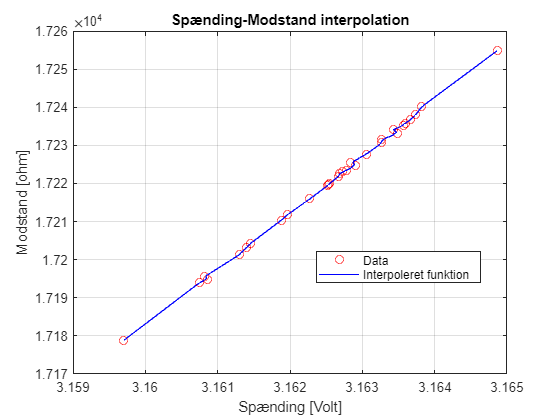


% Data plottes
plot(independ1,depend1, 'ro', 'DisplayName', 'Data'), grid("on")
title('Spænding-Modstand interpolation')
xlabel('Spænding [Volt]')
ylabel('Modstand [ohm]')

hold on

% Fit plottes
plot(brd_lin,dependlin1,'b', 'DisplayName','Interpoleret funktion')

legend('Location','best')
hold off

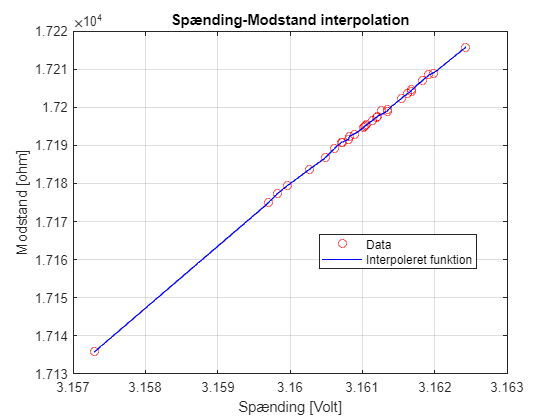

% Afhængig variabel
depend1 = d2_ohm;
% Uafhængig variabel
independ1 = d2_volt;


% Linspace til plot
dependlin1 = linspace(min(depend1), max(depend1));

% Linear fit
brd_lin = interp1(depend1, independ1, dependlin1, 'linear') ;

% Data plottes
plot(independ1,depend1, 'ro', 'DisplayName', 'Data'), grid("on")
title('Spænding-Modstand interpolation')
xlabel('Spænding [Volt]')
ylabel('Modstand [ohm]')

hold on

% Fit plottes
plot(brd_lin,dependlin1,'b', 'DisplayName','Interpoleret funktion')

legend('Location','best')
hold off